# Question 4: Markov Chains and Steady-State Analysis

**(a) Generate a Random Stochastic Matrix**

A Markov chain's transitions are governed by a **stochastic matrix** P, where the entry $P_{\mathrm{ij}}$ is the probability of moving from state i to state j. For this assignment, a $6\times6$ stochastic matrix was required. To ensure each row represents a valid probability distribution (non-negative entries summing to 1), we generated each row using a **Dirichlet distribution**. This was achieved by first drawing six samples from a Gamma distribution and then normalizing each row by dividing by its sum.

**(b) Verify P is a Valid Transition Matrix**

To confirm that the generated matrix P was a valid stochastic matrix, two conditions were programmatically verified:

- **Non-negativity**: We checked that all entries P_ijge0.

- **Row Sums**: We confirmed that the sum of each row equals 1. A small tolerance (${10}^{-9}$) was used when checking the row sums to account for potential floating-point representation errors.

**(c) Choose an Initial State Vector**

The initial state of the system is defined by a probability vector $x_0$, where $x_0$,i is the probability of starting in state i. For this simulation, we chose a deterministic initial state where the system begins in **State 1** with 100% certainty. This is represented by the vector $x_0=[1,0,0,0,0,0]$.

**(d): Simulate the Markov Process**

The evolution of the state vector over time was simulated for 100 steps using the iterative formula: 


$$x_{k+1} =$$

$$x_kP$$


Starting with $x_0$, we repeatedly multiplied the current state vector by the transition matrix P to find the next state. The state vector at each of the 100 time steps was stored in a history matrix for later analysis and visualization.

**(e) Plot the Evolution of the State Vector**

A plot was generated to visualize the behavior of the system over time. The x-axis represented the time step (from 0 to 100), and the y-axis represented the probability of being in each of the six states. The plot clearly showed that the probabilities, which started at their initial values, quickly began to change and then stabilized, approaching constant values. This visual evidence strongly suggests that the system converges to a **steady state**.

**(f) Use Linear Algebra to Find the Steady-State Vector**

The steady-state vector, denoted x_infty, is a probability vector that remains unchanged by the transition matrix, satisfying the equation: 

$x_\infty P=x_\infty $�

This is an eigenvalue problem, which can be rewritten as $x_\infty(P-I)=0$, where I is the identity matrix. This means $x_\infty$ is a **left eigenvector** of P corresponding to the **eigenvalue 1**. To solve this computationally, we worked with the transposed equation: 


$$(P^T-I)x_\infty ^T=0$$


We found the eigenvector of $P^T$ associated with the eigenvalue 1. The resulting vector was then normalized (by dividing by the sum of its elements) to ensure it was a valid probability vector.

**(g) Compare Computed and Simulated Steady-State**

The analytically computed steady-state vector $x_\infty$ was compared with the final vector from the simulation, $x_{100}$. The **Euclidean norm** of the difference between these two vectors was calculated. The resulting value was extremely small, confirming that after 100 iterations, the simulation had effectively converged to the true steady state.

**(h) Compute Eigenvalues and Discuss Convergence**

The convergence of the system is explained by the **Perron-Frobenius theorem**. For a regular stochastic matrix like the one we generated, this theorem guarantees that:

- The largest eigenvalue is 1, and it is unique.

- All other eigenvalues have a magnitude strictly less than 1.

- The eigenvector corresponding to the eigenvalue 1 (the steady-state vector) has all positive components.

When we compute $x_k=x_0P^k$, the components of the state vector associated with eigenvalues of magnitude less than 1 decay to zero as k to $\infty$. The system's long-term behavior is thus dominated by the eigenvector associated with the eigenvalue 1. The rate of convergence is determined by the magnitude of the second-largest eigenvalue.

**(i) Add a Small Perturbation**

To test the system's sensitivity, a small perturbation was introduced to the original matrix P. A random matrix $\delta P$ with small entries was created and added to P. The resulting matrix $P+\delta P$ was then re-normalized (enforcing non-negativity and ensuring rows sum to 1) to make it a valid stochastic matrix, which we called $P_{\mathrm{perturbed}}$.

**(j) Recompute the Steady State and Compare**

The steady-state vector for the new perturbed matrix, $x_{\infty_{\mathrm{perturbed}} }$, was calculated using the same eigenvector method from part (f). This new steady state was then compared to the original steady state $x_\infty$. The norm of their difference was computed, which showed a small but non-zero change, indicating that the steady state is sensitive to changes in transition probabilities, but not unstable.

**(k) Comment on the Implications of This Sensitivity**

The final result showed that small changes in the transition probabilities lead to small changes in the steady-state distribution. This property, known as **stability**, is crucial for real-world models.

- **Internet Search Rankings:** Google's PageRank algorithm models the web as a Markov chain. Its stability ensures that adding or removing a few links doesn't catastrophically alter the entire ranking system.

- **Weather Prediction:** Long-term climate models rely on the steady state of weather transitions. If these models were highly sensitive, small errors in measuring daily transition probabilities would make long-term climate predictions completely unreliable.

%--------------------------------------------------------------------------
% MATLAB SCRIPT FOR MARKOV CHAIN ANALYSIS
%--------------------------------------------------------------------------

%% Setup
clear; clc; close all;
n = 6; % Size of the matrix (number of states)
rng('default'); % Set the random seed for reproducibility


%% (a) Generate a Random Stochastic Matrix P
fprintf('--- Part (a): Generating Matrix ---\n');

--- Part (a): Generating Matrix ---


% Generate each row from a Dirichlet distribution by sampling from a Gamma
% distribution and normalizing.
alpha = ones(1, n); % Parameters for the Dirichlet distribution
P = gamrnd(repmat(alpha, n, 1), 1);
P = P ./ sum(P, 2); % Normalize each row to sum to 1

disp('Generated Stochastic Matrix P:');

Generated Stochastic Matrix P:


disp(P);

    0.6081    0.0875    0.0765    0.0833    0.0185    0.1261
    0.1899    0.3196    0.0240    0.1102    0.3302    0.0260
    0.0071    0.2770    0.0106    0.0679    0.1076    0.5299
    0.1609    0.0142    0.0326    0.2154    0.3354    0.2416
    0.4239    0.1745    0.1510    0.1158    0.0393    0.0956
    0.1107    0.3445    0.0396    0.1314    0.3644    0.0094



fprintf('\n');


%% (b) Verify P is a Valid Transition Matrix
fprintf('--- Part (b): Verifying Matrix ---\n');

--- Part (b): Verifying Matrix ---


isNonNegative = all(P >= 0, 'all');
rowSums = sum(P, 2);
tolerance = 1e-9;
rowsSumToOne = all(abs(rowSums - 1) < tolerance);

if isNonNegative && rowsSumToOne
    disp('Verification successful: P is a valid stochastic matrix.');
else
    disp('Verification failed: P is not a valid stochastic matrix.');
end

Verification successful: P is a valid stochastic matrix.


fprintf('\n');


%% (c) Choose an Initial State Vector x0
fprintf('--- Part (c): Initial State Vector ---\n');

--- Part (c): Initial State Vector ---


x0 = zeros(1, n);
x0(1) = 1; % Start in State 1 with 100% probability

disp('Initial state vector x0:');

Initial state vector x0:


disp(x0);

     1     0     0     0     0     0



fprintf('\n');


%% (d) Simulate the Markov Process for 100 Time Steps
fprintf('--- Part (d): Simulating the Process ---\n');

--- Part (d): Simulating the Process ---


num_steps = 100;
x_history = zeros(num_steps + 1, n);
x_history(1, :) = x0;
x_current = x0;

for k = 1:num_steps
    x_current = x_current * P;
    x_history(k + 1, :) = x_current;
end

disp('Simulation complete.');

Simulation complete.


disp('Final state vector after 100 steps (x_100):');

Final state vector after 100 steps (x_100):


disp(x_history(end, :));

    0.3489    0.1805    0.0653    0.1136    0.1641    0.1276



fprintf('\n');


%% (e) Plot the Evolution of the State Vector
fprintf('--- Part (e): Plotting the Evolution ---\n');

--- Part (e): Plotting the Evolution ---


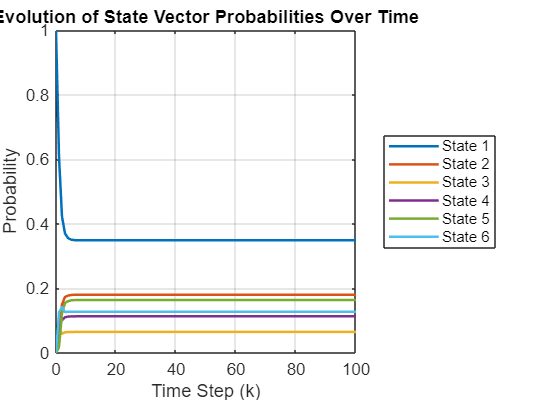

figure;
plot(0:num_steps, x_history, 'LineWidth', 1.5);
title('Evolution of State Vector Probabilities Over Time');
xlabel('Time Step (k)');
ylabel('Probability');
legend('State 1', 'State 2', 'State 3', 'State 4', 'State 5', 'State 6', 'Location', 'eastoutside');
grid on;
ylim([0, 1]);

disp('Plot generated. The state probabilities converge to stable values.');

Plot generated. The state probabilities converge to stable values.


fprintf('\n');


%% (f) Use Linear Algebra to Find the Steady-State Vector x_inf
fprintf('--- Part (f): Computing the Steady-State Vector ---\n');

--- Part (f): Computing the Steady-State Vector ---


% To solve x_inf * P = x_inf, we find the eigenvector of P' for eigenvalue 1.
% This is equivalent to finding the null space of (P' - I).
[V, D] = eig(P');
eigenvalues = diag(D);

% Find the index of the eigenvalue closest to 1
[~, idx] = min(abs(eigenvalues - 1));
x_inf = V(:, idx)'; % Get the corresponding eigenvector and transpose

% Normalize the vector so its components sum to 1
% Take the real part to handle any minor complex numerical errors
x_inf = real(x_inf / sum(x_inf));

disp('Computed steady-state vector x_inf:');

Computed steady-state vector x_inf:


disp(x_inf);

    0.3489    0.1805    0.0653    0.1136    0.1641    0.1276



fprintf('\n');


%% (g) Compare Computed Steady-State with Final Simulation
fprintf('--- Part (g): Comparing Simulation with Analytical Solution ---\n');

--- Part (g): Comparing Simulation with Analytical Solution ---


x_final_sim = x_history(end, :);
comparison_diff = norm(x_final_sim - x_inf);

fprintf('The Euclidean norm of the difference is: %e\n', comparison_diff);

The Euclidean norm of the difference is: 4.721141e-15


disp('The small difference confirms the simulation converged correctly.');

The small difference confirms the simulation converged correctly.


fprintf('\n');


%% (h) Compute Eigenvalues of P and Discuss Convergence
fprintf('--- Part (h): Eigenvalue Analysis ---\n');

--- Part (h): Eigenvalue Analysis ---


eigenvalues_P = eig(P);
disp('Eigenvalues of P:');

Eigenvalues of P:


disp(eigenvalues_P);

   1.0000 + 0.0000i
   0.3065 + 0.0000i
  -0.1008 + 0.1770i
  -0.1008 - 0.1770i
   0.1110 + 0.0000i
  -0.0136 + 0.0000i




disp('Magnitude of eigenvalues:');

Magnitude of eigenvalues:


disp(abs(eigenvalues_P));

    1.0000
    0.3065
    0.2037
    0.2037
    0.1110
    0.0136



disp('As predicted by the Perron-Frobenius theorem, there is one eigenvalue of 1,');

As predicted by the Perron-Frobenius theorem, there is one eigenvalue of 1,


disp('and all other eigenvalues have magnitudes less than 1.');

and all other eigenvalues have magnitudes less than 1.


fprintf('\n');


%% (i) Add a Small Perturbation to P
fprintf('--- Part (i): Perturbing the Matrix ---\n');

--- Part (i): Perturbing the Matrix ---


delta = 0.01; % Magnitude of perturbation
deltaP = (rand(n) - 0.5) * delta; % Create small random changes
P_perturbed = P + deltaP;

% Re-normalize to ensure the matrix remains stochastic
P_perturbed(P_perturbed < 0) = 0; % Enforce non-negativity
P_perturbed = P_perturbed ./ sum(P_perturbed, 2); % Normalize rows

disp('A small perturbation was added and the matrix was re-normalized.');

A small perturbation was added and the matrix was re-normalized.


fprintf('\n');


%% (j) Recompute the Steady State and Compare
fprintf('--- Part (j): Analyzing Sensitivity ---\n');

--- Part (j): Analyzing Sensitivity ---


% Calculate the steady state for the new perturbed matrix
[V_p, D_p] = eig(P_perturbed');
eigenvalues_p = diag(D_p);
[~, idx_p] = min(abs(eigenvalues_p - 1));
x_inf_perturbed = V_p(:, idx_p)';
x_inf_perturbed = real(x_inf_perturbed / sum(x_inf_perturbed));

disp('Original steady state:');

Original steady state:


disp(x_inf);

    0.3489    0.1805    0.0653    0.1136    0.1641    0.1276



disp('New steady state (after perturbation):');

New steady state (after perturbation):


disp(x_inf_perturbed);

    0.3488    0.1827    0.0655    0.1111    0.1645    0.1275




sensitivity_diff = norm(x_inf - x_inf_perturbed);
fprintf('The norm of the difference between the two steady states is: %e\n', sensitivity_diff);

The norm of the difference between the two steady states is: 3.360354e-03


fprintf('\n');


%% (k) Comment on the Implications of This Sensitivity
fprintf('--- Part (k): Implications of Sensitivity ---\n');

--- Part (k): Implications of Sensitivity ---


disp('The small change in the steady-state vector due to a small perturbation');

The small change in the steady-state vector due to a small perturbation


disp('in P suggests that the system is stable. This is a crucial property for');

in P suggests that the system is stable. This is a crucial property for


disp('real-world models like search engine ranking and climate prediction, as it');

real-world models like search engine ranking and climate prediction, as it


disp('ensures that minor errors or changes do not lead to wildly different outcomes.');

ensures that minor errors or changes do not lead to wildly different outcomes.


fprintf('\n');